# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Load the water quality data
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids);
Junction_SelectIdx = Junction_SelectIdx([1,2,4,5,7,8,9]);
cext = wq_data.chlorine([3,6],:);

Assign chlorine decay parameters.

% Link bulk reaction coefficients
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

% Link wall decay reaction coefficients... apply by pipe size for S&G?
% theta = ones(np,1); % units of m/day
% for k = 1:np
%     if D(k) <= 75
%         theta(k) = 0.25;
%     elseif D(k) > 75 && D(k) <= 150
%         theta(k) = 0.175;
%     elseif D(k) > 150 && D(k) <= 250
%         theta(k) = 0.1;
%     else
%         theta(k) = 0.05;
%     end
% end
% 
% net.setLinkWallReactionCoeff(1:np, -theta);
% net.setOptionsPipeWallReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% % Assign source chlorine with time varying pattern
% cext = ones(n0,nt);
% 
% % Constant source concentration for n0 reservoirs
% % cext = cext*0.25;
% 
% % Varying source concentration by source element
% source_c = [1.00, 0.85];

% for j = 1:n0
%     cext(j,:) = source_c(j)*cext(j,:);
% end

% Varying source concentration by source element with
% concentration spike (pulse) at t = 12
% t = 144;
% for i = 1:4*days*nt
%     for j = 1:n0
%         if i == t
%             cext(j,i) = 1*cext(j,i); % Pulse of 1 mg/L
%         else
%             cext(j,i) = source_c(j)*cext(j,i);
%         end
%     end
% end

base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

### Genetic Algorithm Preparation

Implement genetic algoritnm to solve the parameter optimization problem.

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Obs = wq_data.chlorine([1,2,4,5,7,8,9],:);

Plot the simulated chlorine concentration for visualisation.

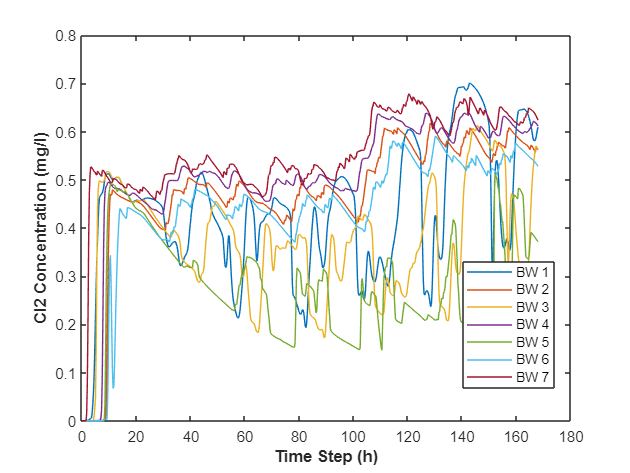

% create the plot for simulated chlorine concentration
for i = 1:length(Junction_SelectIdx)
    Junction_Name{i} = sprintf('BW %d',i);
end
figure
for i = 1:length(Junction_SelectIdx)
        plot(0:0.25:days*24,c_nodes_Sim(i,:),'-')
    hold on
end

legend(Junction_Name,'location','best');
xlabel('Time Step (h)','fontweight','bold')
ylabel('Cl2 Concentration (mg/l)','fontweight','bold')

According to the water age analysis, the longest water age before periodic behaviour is approxiamately 40 hours, thus we split the data into three parts, the first part is a 2-day stabilisation period, the second part is a 1-day train data, the last part is the 4-day validation time.

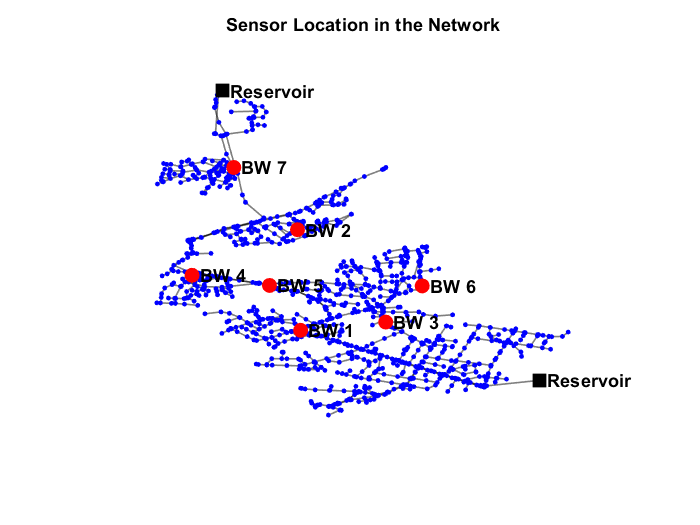

% Data splitting
c_nodes_Sim = c_nodes_Sim(:,2:end);
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_before = mse_function(Sim_train,Obs_train);

% Plot the sensor location on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 2;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,Junction_SelectIdx,'NodeColor','r','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';

axis('off')
title('Sensor Location in the Network')

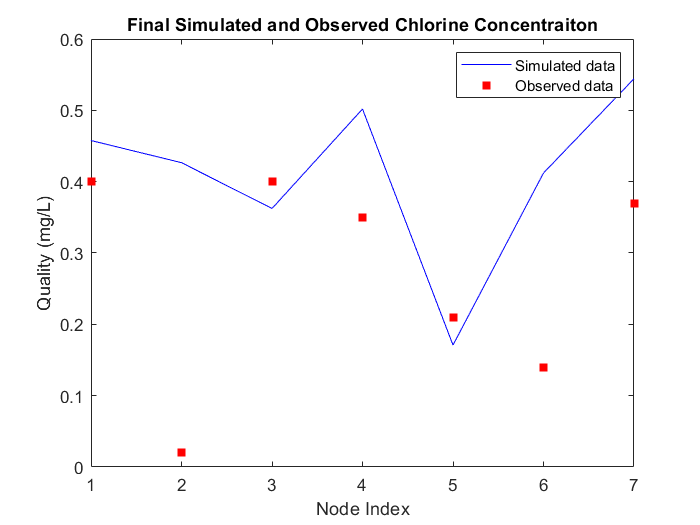

% Plot the calibrated quality-time figure
figure,
plot(1:7,Sim_train(:,96),'-b')
hold on
scatter(1:7,Obs_train(:,96),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:7);
title('Final Simulated and Observed Chlorine Concentraiton')

### No Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on one group.

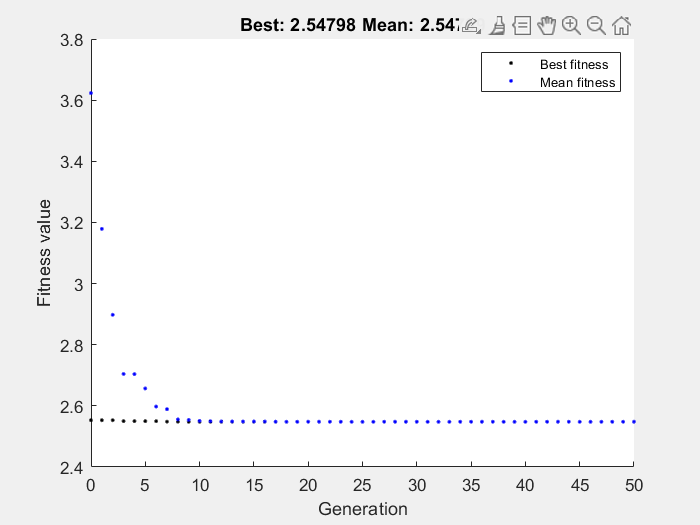

% % genetic algorithm implementation
rng default
% options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',1,'InitialPopulation', ...
%     100,'Generations',100,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50,'InitialPopulation',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10;
ub = 0;

Mse_function = @(x) Mse_NoGroup(x,Obs_train,Junction_SelectIdx);
[x_NoGroup, fval_NoGroup] = ga(Mse_function,1,[],[],[],[],lb,ub,[],options);

% Test the ga result
theta_NoGroup = ones(2281,1); % units of m/day
for i = 1:2281
    theta_NoGroup(i) = x_NoGroup(1);
end
net.setLinkBulkReactionCoeff(1:np, theta_NoGroup);
net.setOptionsPipeBulkReactionOrder(1);
quality_res_NoGroup = net.getComputedQualityTimeSeries;

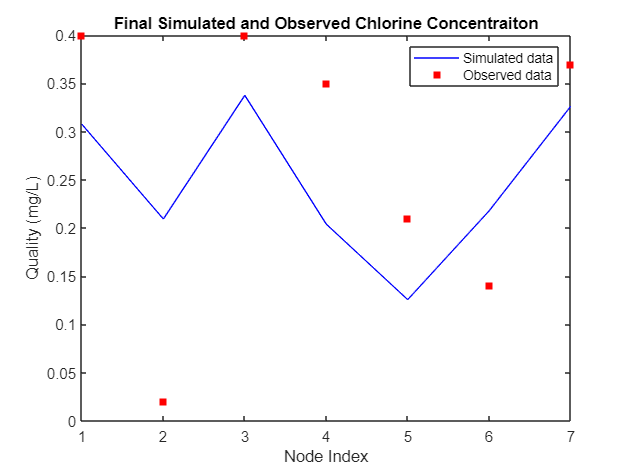

net.getLinkBulkReactionCoeff;
c_nodes_NoGroup = quality_res_NoGroup.NodeQuality';
c_nodes_Sim_NoGroup = c_nodesNew(Junction_SelectIdx,2:end);
Sim_NoGroup_train = c_nodes_SimNew(:,2*96+1:3*96);
mse_after_NoGroup = mse_function(Sim_NoGroup_train,Obs_train);

% Plot the ga-modified quality-time figure
figure,
plot(1:7,Sim_NoGroup_train(:,96),'-b')
hold on
scatter(1:7,Obs_train(:,96),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:7);
title('Final Simulated and Observed Chlorine Concentraiton')

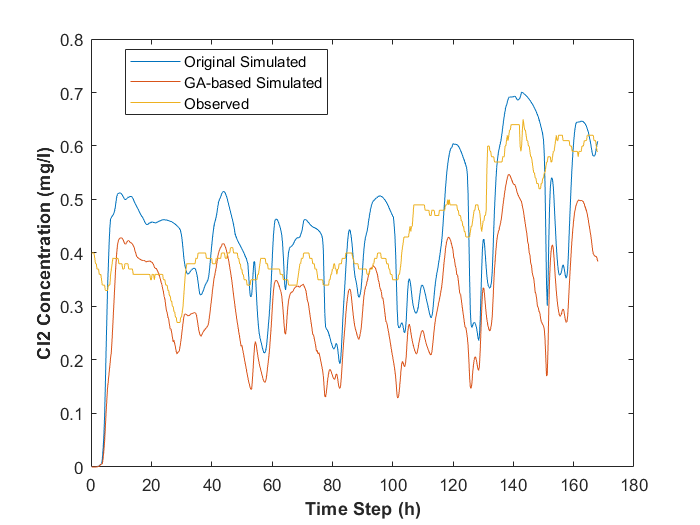

% BW1 as an example
figure
plot(0.25:0.25:days*24,c_nodes_Sim(1,:),'-')
hold on
plot(0.25:0.25:days*24,c_nodes_Sim_NoGroup(1,:),'-')
hold on
plot(0.25:0.25:days*24,c_nodes_Obs(1,:),'-')

legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
xlabel('Time Step (h)','fontweight','bold')
ylabel('Cl2 Concentration (mg/l)','fontweight','bold')

fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_NoGroup);

The mse before calibration is 0.0593, after calibration it is 0.0153

### Diameter based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on diameter groups.

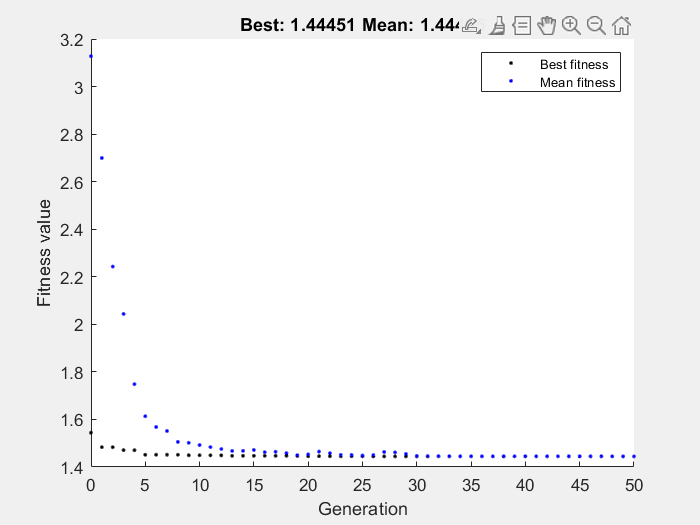

% % genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = [-10,-10,-10,-10];
ub = [0,0,0,0];

Mse_function = @(x) Mse_D(x,Obs_train,Junction_SelectIdx,D);
[x_D, fval_D] = ga(Mse_function,4,[],[],[],[],lb,ub,[],options);

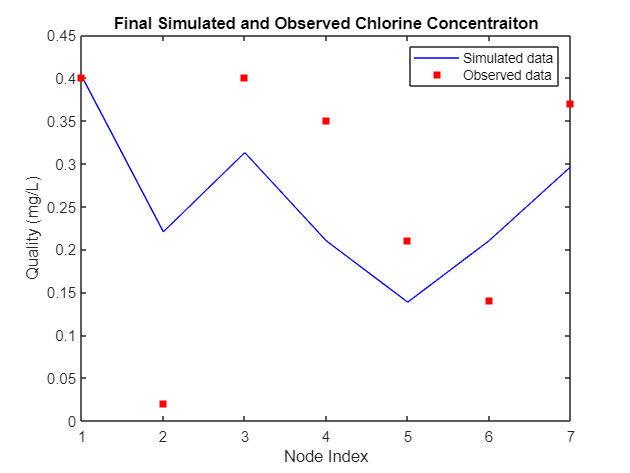


% Test the ga result
theta_D = ones(2281,1); % units of m/day
for i = 1:2281
    if D(i) <= 75
        theta_D(i) = x_D(1);
    elseif D(i) > 75 && D(i) <= 150
        theta_D(i) = x_D(2);
    elseif D(i) > 150 && D(i) <= 250
        theta_D(i) = x_D(3);
    else
        theta_D(i) = x_D(4);
    end
end
net.setLinkBulkReactionCoeff(1:np, theta_D);
net.setOptionsPipeBulkReactionOrder(1);
quality_res_D = net.getComputedQualityTimeSeries;
c_nodes_D = quality_res_D.NodeQuality';
c_nodes_Sim_D = c_nodes_D(Junction_SelectIdx,2:end);

Sim_D_train = c_nodes_Sim_D(:,2*96+1:3*96);
mse_after_D = mse_function(Sim_D_train,Obs_train);

% Plot the ga-modified quality-time figure
figure,
plot(1:7,Sim_D_train(:,96),'-b')
hold on
scatter(1:7,Obs_train(:,96),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:7);
title('Final Simulated and Observed Chlorine Concentraiton')

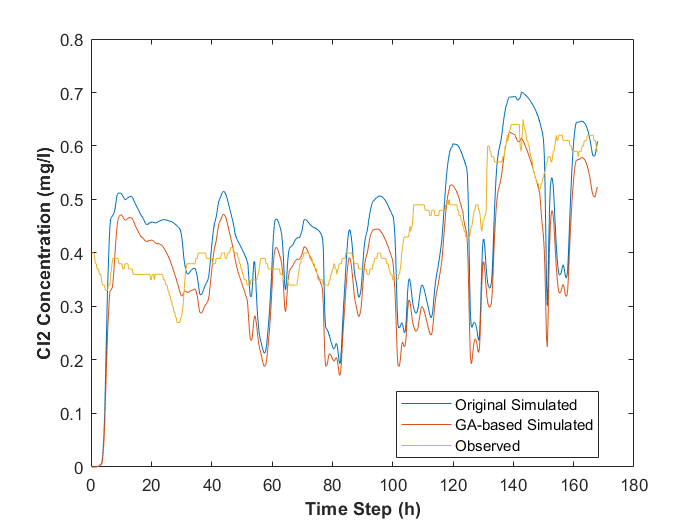


% Node 753 as an example
figure
plot(0.25:0.25:days*24,c_nodes_Sim(1,:),'-')
hold on
plot(0.25:0.25:days*24,c_nodes_Sim_D(1,:),'-')
hold on
plot(0.25:0.25:days*24,c_nodes_Obs(1,:),'-')

legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
xlabel('Time Step (h)','fontweight','bold')
ylabel('Cl2 Concentration (mg/l)','fontweight','bold')

fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_D);

The mse before calibration is 0.0593, after calibration it is 0.0139